# Project 2

Theodore Janson - 260868223

Brandon Freiberger - 260739743

David Schier - 260827890 	 

______________________________________________________

Circuit parameters

global R c Vt Is A f
R = 50; %ohm
c = 10^-6; %farad
Vt = 0.025; %thermal voltage
Is = 10^-13; %diode saturation curren
A = 5; %folts
f = 60; %Hz

Simulation parameters

global dt tolerance
T = 0.5; %simulation time (s)
dt = 10^-4; %step time (s)
tolerance = 10^-5;

Simulate circuit

V1 = zeros(1, T/dt);
V2 = zeros(1, T/dt);
V3 = zeros(1, T/dt);
Ie = zeros(1, T/dt);
check = zeros(1, T/dt);
iterations = zeros(1, T/dt);


Xout = [0;0;0;0];
for t = 0:dt:T
    [Xout, i] = NewtonRaphson(Xout, t);
    j = int32(t/dt + 1);
    V1(j) = Xout(1);
    V2(j) = Xout(2);
    V3(j) = Xout(3);
    Ie(j) = Xout(4);
    iterations(j) = i;
end

Results

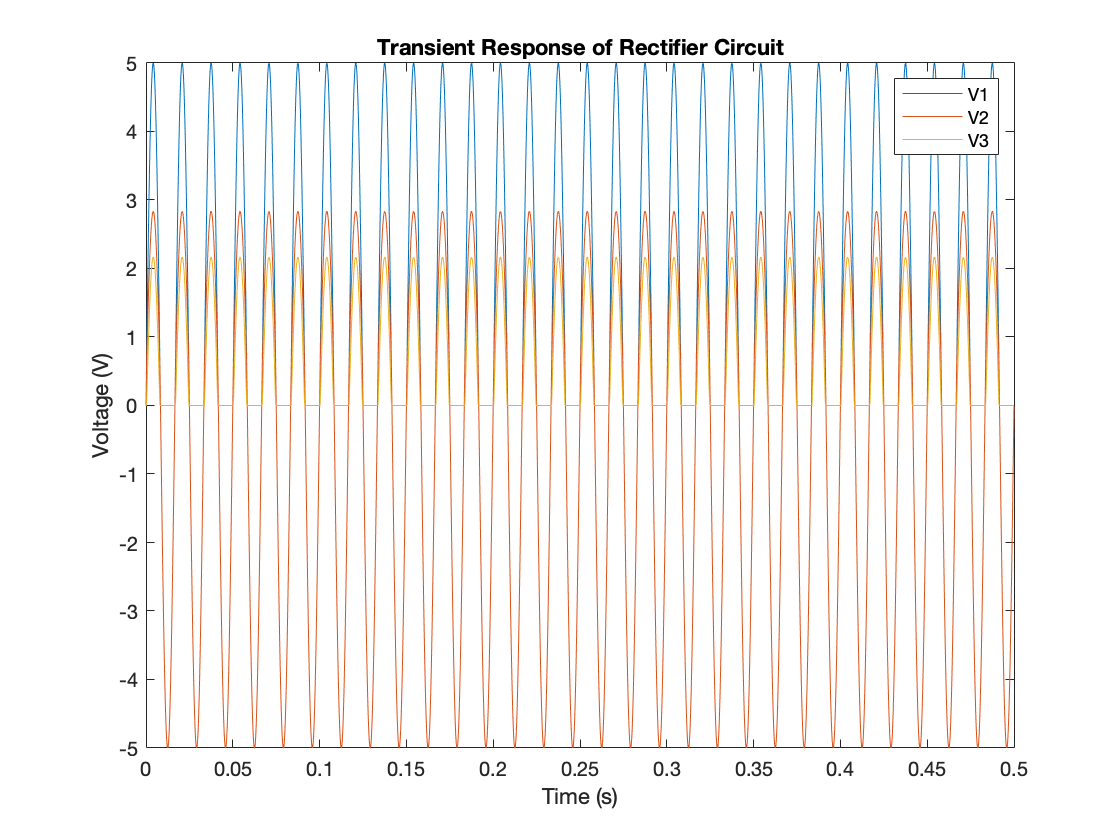

t = 0:dt:T;
figure
plot(t, V1)
hold on;
plot(t, V2)
hold on;
plot(t, V3)
hold off;
legend('V1', 'V2', 'V3')
xlabel('Time (s)')
ylabel('Voltage (V)')
title('Transient Response of Rectifier Circuit')

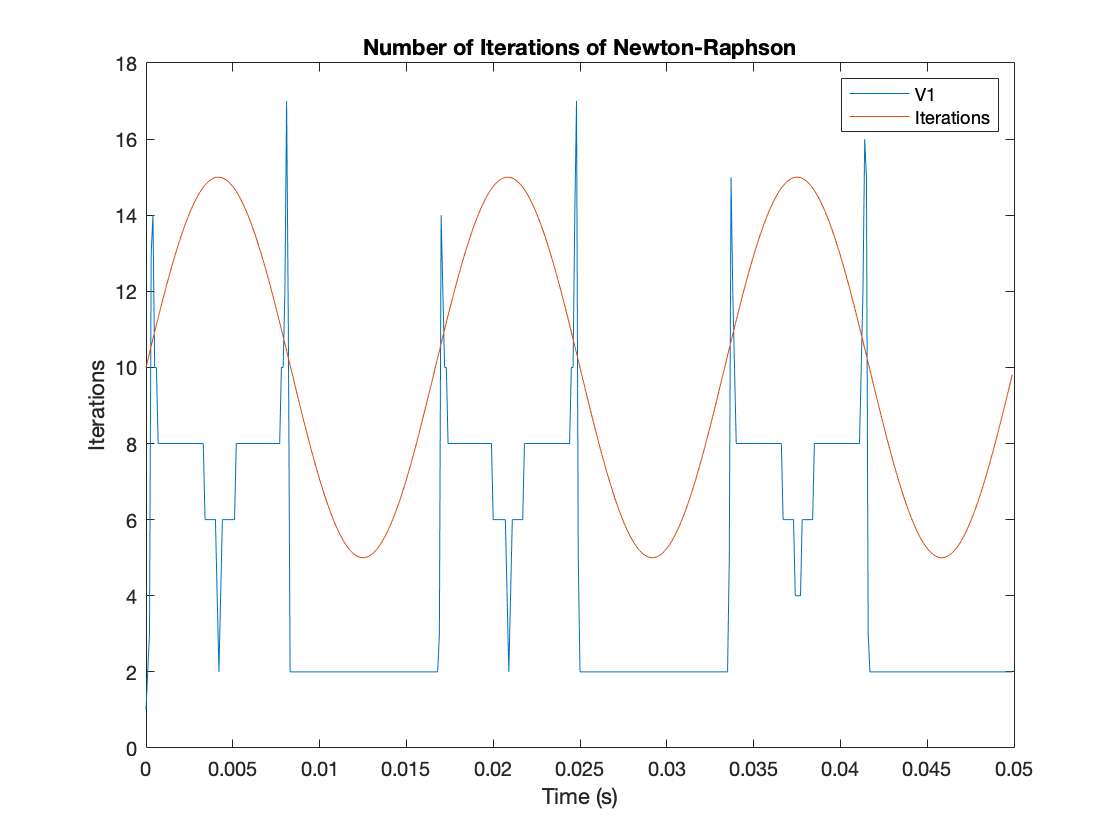


figure
plot(t(1:500), iterations(1:500))
hold on
plot(t(1:500), V1(1:500)+10)
hold off;
legend('V1', 'Iterations')
xlabel('Time (s)')
ylabel('Iterations')
title('Number of Iterations of Newton-Raphson')

function dFx = EvaluateJacobian(X)
    global R c Vt Is dt
    V2 = X(2);
    V3 = X(3);
    dId = (Is/Vt)*exp((V2-V3)/Vt); %derivative of Id wrt V2
    
    G = [1/R -1/R 0 1; -1/R 1/R 0 0; 0 0 1/R 0; 1 0 0 0];
    C = [0 0 0 0; 0 0 0 0; 0 0 c 0; 0 0 0 0];

    dDx = [0 0 0 0; 0 dId -dId 0; 0 -dId dId 0; 0 0 0 0];
    dFx = G + (1/dt)*C + dDx;
end

function Fx = EvaluateSystem(X, X0, t)
    global R c Vt Is dt f A
    V1 = A*sin(2*pi*f*t);
    V2 = X(2);
    V3 = X(3);
    Id = Is*(exp((V2-V3)/Vt)-1);
    G = [1/R -1/R 0 1; -1/R 1/R 0 0; 0 0 1/R 0; 1 0 0 0];
    C = [0 0 0 0; 0 0 0 0; 0 0 c 0; 0 0 0 0];
    Dx = [0 ; Id ; -Id ; 0];
    B = [0 ; 0 ; 0 ; V1];
    Fx = (G + (1/dt)*C)*X + Dx - B - (1/dt)*C*X0;   
end

function [Xout, iterations] = NewtonRaphson(Xin,  t)
    global tolerance 
    i = 0;
    X = Xin;
    X0 = Xin;
    while true
        
        system = EvaluateSystem(X, X0, t);
        jacobian = EvaluateJacobian(X);
        Xnew = X - jacobian\system;

        convergence = norm(EvaluateSystem(Xnew, X, t), 2);
        difference = norm(Xnew-X, 2);        
        tempX = X;
        X = Xnew;
        X0 = tempX;
        
        i = i + 1;
        
        if i > 1000
            disp('Algorithm did not converge')
            iterations = i;
            Xout = X;
            break
        end
        if convergence < tolerance && difference < tolerance
            iterations = i;
            Xout = X;  
            break
        end
    end 
end